# Reduced order model from measurements of the full state space

This is an example of how to reconstruct a slow 2D SSM of a 3-degree of freedom mechanical system using synthetic measurements of the full state space. In this example, we consider a 3-degree of freedom damped oscillator chain with an additional nonlinear spring attached to the leftmost mass.

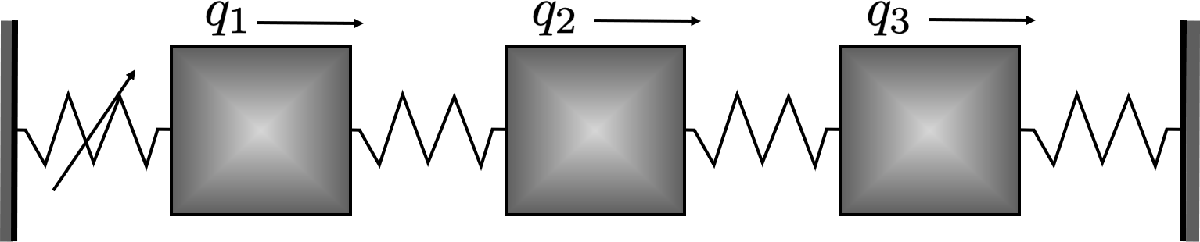

clearvars
close all

## Example setup

The $N$-degree of freedom dynamical system is of the form


$$\mathbf{M\ddot{q}} + \mathbf{C\dot{q}} + \mathbf{Kq} + \mathbf{f}(\mathbf{q},\mathbf{\dot{q}}) = \mathbf{0}$$


where $\mathbf{f}=\mathcal{O}(|\mathbf{q}|^2,|\mathbf{\dot{q}}|^2,|\mathbf{q}||\mathbf{\dot{q}}|)$ represents the nonlinearities and $\mathbf{M}$, $\mathbf{C}$, and $\mathbf{K}$ are the $N\times N$ mass, stiffness, and damping matrices, respectively.

nTraj = 6;
indTest = [1 5];
indTrain = setdiff(1:nTraj, indTest);

N = 3;
mass = 1;
stiffness = 1;
damping = 0.006;
M = mass*eye(N);
K = stiffness*(2*eye(N) - diag(ones(1,N-1),-1) - diag(ones(1,N-1),1));
C = K; C(1,1) = 4; C(end,end) = 3; C = damping*C;

% nonlinearities
F2 = sptensor(zeros(2*N, 2*N, 2*N));
F2(1,N+1,N+1) = 0.33;    % q1dot^2
F3 = sptensor(zeros(2*N, 2*N, 2*N, 2*N));
F3(1,1,1,1) = 2;         % q1^3
F3(1,1,1,N+1) = 0.3;     % q1^2*q1dot^2 
F3(1,N+1,N+1,N+1) = 0.5; % q1dot^3
fnl = {F2, F3};
f = @(q,qdot) [F2(1,N+1,N+1)*qdot(1).^2 + F3(1,1,1,1)*q(1).^3 + F3(1,1,1,N+1)*q(1).^2.*qdot(1) + F3(1,N+1,N+1,N+1)*qdot(1).^3;
               zeros(N-1,1)];
% f = @(t,x) DS.odefun(t,x)

We rewrite the system in first-order form as


$$\mathbf{\dot{x}} = \mathbf{A}\mathbf{x} + \mathbf{G}(\mathbf{x})$$


with

$\mathbf{x}=\left[\begin{array}{c}\mathbf{q}\\\dot{\mathbf{q}}\end{array}\right],\quad\mathbf{A}=\left[\begin{array}{cc}\mathbf{0} 
& \mathbf{I}\\-\mathbf{M}^{-1}\mathbf{K} & -\mathbf{M}^{-1}\mathbf{C} \end{array}\right],\quad\mathbf{G}(\mathbf{x})=\left[\begin{array}{c} \mathbf{0} \\ -\mathbf{M}^{-1}\mathbf{f}(\mathbf{x})\end{array}\right]$.

A = [zeros(N), eye(N);
    -M\K,     -M\C];
G = @(x) [zeros(N,1);
         -M\f(x(1:N),x(N+1:2*N))];
F = @(t,x) A*x + G(x);

Now we use SSMTool 2.0 [1] to compute a manifold tangent to the two slowest eigenmodes. We use the obtained manifold to set trajectory initial conditions that will lie close to it. We however do not use the computed manifold in the subsequent manifold fitting.

[1]  [https://github.com/haller-group/SSMTool-2.0/releases](https://github.com/haller-group/SSMTool-2.0/releases) 

DS = DynamicalSystem();
set(DS, 'M', M, 'C', C, 'K', K, 'fnl', fnl);
set(DS.Options,'Emax',5,'Nmax',10,'notation','multiindex')
S = SSM(DS);
set(S.Options, 'reltol', 0.1,'notation','multiindex')
S.choose_E([1,2]);


 The first 6 eigenvalues are given as 
   -0.0040074 +    0.76536i
   -0.0040074 -    0.76536i
      -0.0105 +     1.4142i
      -0.0105 -     1.4142i
    -0.012493 +     1.8477i
    -0.012493 -     1.8477i

No (near) outer resonances detected in the (truncated) spectrum
sigma_out = 3
(near) inner resonance detected for the following combination of master eigenvalues
     2     1
     1     2

These are in resonance with the follwing eigenvalues of the master subspace
   -0.0040074 +    0.76536i
   -0.0040074 -    0.76536i

sigma_in = 3


mfd = S.compute_whisker(20);

Manifold computation time at order 2 = 00:00:00
Estimated memory usage at order  2 = 1.57E-02 MB
Manifold computation time at order 3 = 00:00:00
Estimated memory usage at order  3 = 1.87E-02 MB
Manifold computation time at order 4 = 00:00:00
Estimated memory usage at order  4 = 2.14E-02 MB
Manifold computation time at order 5 = 00:00:00
Estimated memory usage at order  5 = 2.65E-02 MB
Manifold computation time at order 6 = 00:00:00
Estimated memory usage at order  6 = 3.14E-02 MB
Manifold computation time at order 7 = 00:00:00
Estimated memory usage at order  7 = 3.93E-02 MB
Manifold computation time at order 8 = 00:00:00
Estimated memory usage at order  8 = 4.72E-02 MB
Manifold computation time at order 9 = 00:00:00
Estimated memory usage at order  9 = 5.87E-02 MB
Manifold computation time at order 10 = 00:00:00
Estimated memory usage at order  10 = 7.04E-02 MB
Manifold computation time at order 11 = 00:00:00
Estimated memory usage at order  11 = 8.63E-02 MB
Manifold computation time 


IC = zeros(2*N, nTraj);
for iTraj = 1:nTraj
    z = 0.4*(-1)^(2*iTraj/nTraj);
    IC(:,iTraj) = real(getManifoldPoint(mfd, [z; conj(z)]));
end

## Generation of Synthetic Data

Having set up the dynamics of the problem, we now move on to generate synthetic data, which will be used to fit a parametrisation of the manifold. We will divide the data into a training set, for model fitting, and a testing set, for validation. The data is generated by integrating the system.

xSim = cell(nTraj, 2);
for iTraj = 1:nTraj
    [t, x] = ode45(F, linspace(0, 1000, 1e4), IC(:, iTraj));
    xSim{iTraj,1} = t';
    xSim{iTraj,2} = x';
end

## Datadriven manifold fitting

The measured trajectories are assumed to lie close to a two-dimensional manifold that is tangent at the origin to the eigenspace corresponding to the slowest pair of eigenvalues. We now want to fit a polynomial of order $M$ to the data points to approximate the manifold. Here we use a graph style parametrization, meaning that the manifold is parametrized using coordinates in the computed eigenspace. This excludes the possibility of folds on the manifold (however, if necessary we may circumvent this problem by increasing the dimensionality of the observed space). 

SSMDim = 2;
SSMOrder = 3;
overEmbed = 0;
data = coordinates_embedding(xSim(indTrain,:), SSMDim, 'OverEmbedding', overEmbed);

The embedding coordinates consist of the measured states.


tData = data(:,1); xData = data(:,2);

The eigenspace $V_e$ of the two slowest modes is unknown in this case. Trajectories are assumed to lie close to an invariant manifold that is tangent to this eigenspace, as shown in the figure below.

 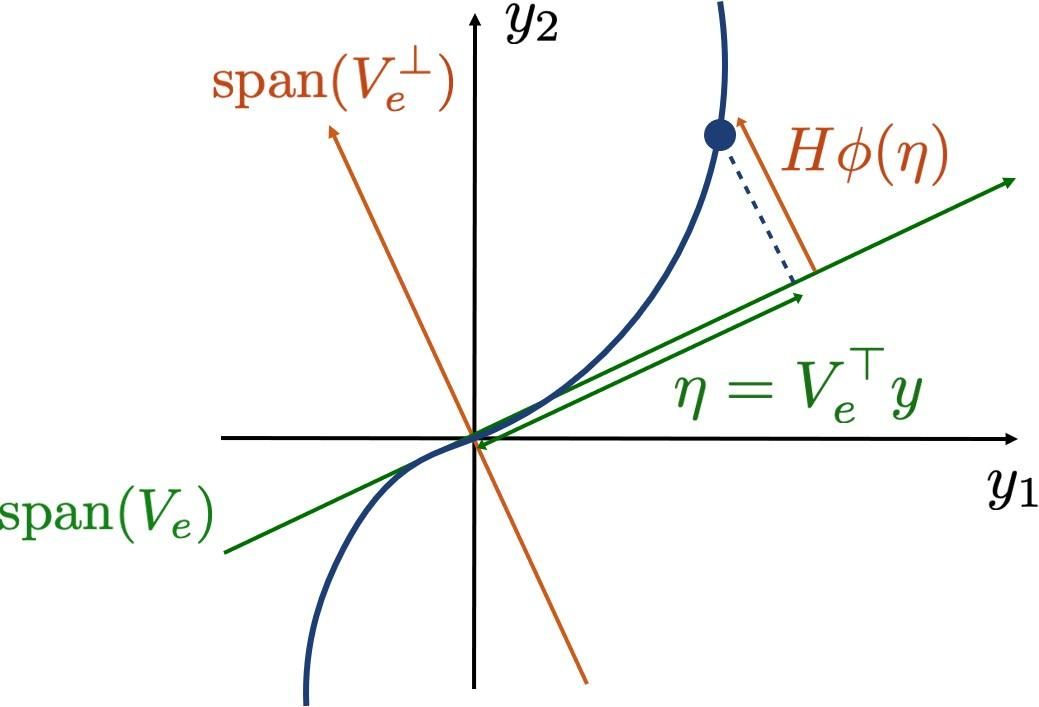

We therefore seek the $2N\times m_M$ polynomial coefficient matrix $H$ of the manifold on the form

$y = V_e V_e^\top y + H \phi_{m,2:M}(V_e^\top y) $,

where the function $\phi_{m,2:M}(q)$ computes a vector of all $m_M$ monomials from orders 2 up to $M$ of an $m$-vector $q$. This optimization problem amounts to minimising a cost function computed from the measured data $y_k$,


$$C_r(V_e,H) = \sum_{k=1}^N ||y_k - V_eV_e^\top - H\phi_{m,2:M}(V_e^\top y_k) ||$$


to find $H$ and the $2N\times 2$ eigenspace matrix $V_e$, under the constraints that $V_e^\top H=0$ and $V_e^\top V_e = I$. The minimization is performed with the Matlab function `fmincon` in `IMparametrization`.

[V, SSMFunction, H] = IMparametrization(data, SSMDim, SSMOrder);

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    1.083586e-06    6.661e-16    4.775e-05
    1       2    1.079104e-06    3.275e-09    4.733e-05    6.707e-05
    2       3    1.057387e-06    8.046e-08    4.524e-05    3.327e-04
    3       4    9.650090e-07    1.855e-06    3.515e-05    1.599e-03
    4       5    7.935908e-07    3.005e-05    1.111e-05    6.444e-03
    5       6    7.930422e-07    2.354e-08    1.131e-05    1.892e-04
    6       7    7.922863e-07    7.019e-09    1.143e-05    1.210e-04
    7       8    7.883561e-07    9.655e-08    1.170e-05    4.317e-04
    8       9    7.721644e-07    2.226e-06    1.233e-05    2.001e-03
    9      10    7.585326e-07    1.366e-06    1.201e-05    1.616e-03
   10      11    7.393865e-07    2.283e-06    1.143e-05    2.424e-03
   11      12    7.318858e-07    6.176e-07    1.157e-05    1.147e-03
   12      13    7.302631e-07    1.900e-07    1

## Plot and validation

We plot the computed manifold embedding and calculate the deviation of the test data from the reduced model to evaluate the quality of model predictions.

figure
hold on
meanDist = zeros(length(indTest),1);
for i = 1:length(indTest)
    iTraj = indTest(i);
    y = V'*xSim{iTraj,2};
    plot(y(1,:), y(2,:))
    meanDist(i) = mean(vecnorm(xSim{iTraj,2} - SSMFunction(y)));
end
RRMS = mean(meanDist)

RRMS =     0.0014203


RRMS is the root mean square error of the reconstruction.

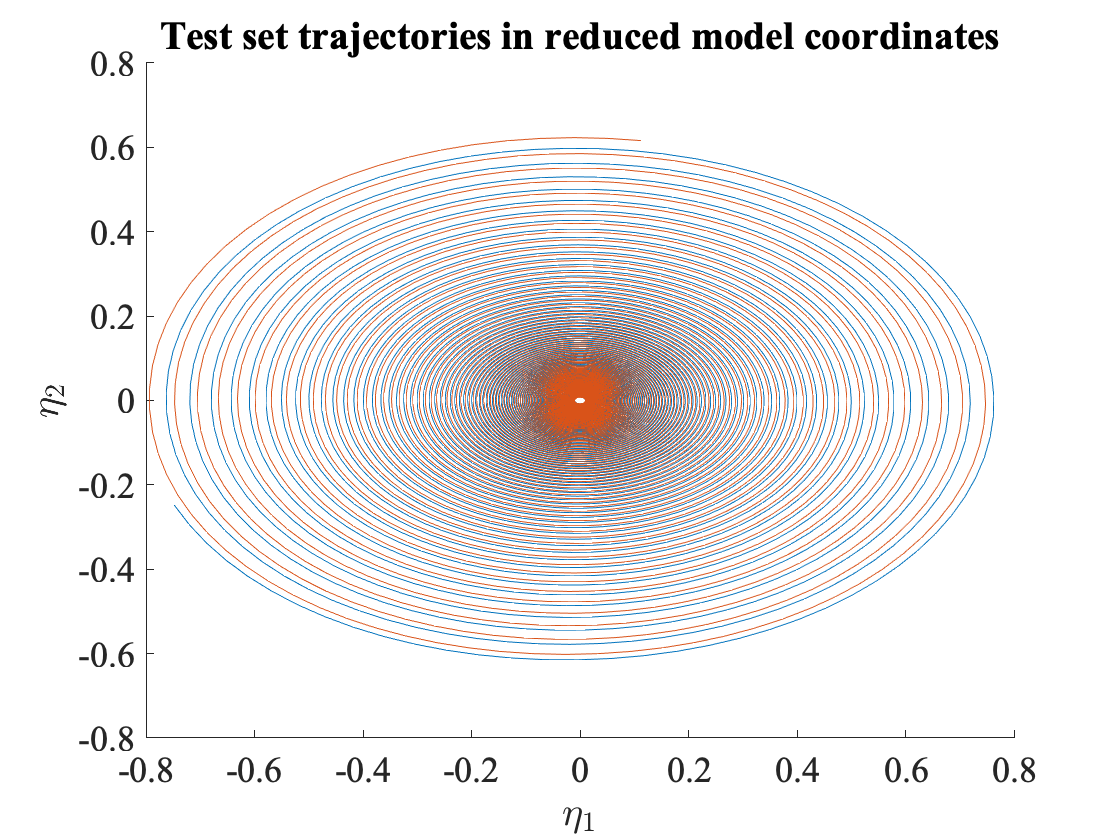

xlabel('$\eta_1$', 'Interpreter', 'latex')
ylabel('$\eta_2$', 'Interpreter', 'latex')
title('Test set trajectories in reduced model coordinates')
set(gca, 'fontname', 'times')
set(gca, 'fontsize', 18)

For the first degree of freedom, we compare the full dynamics to the reduced model, where we have projected the trajectory onto the manifold.

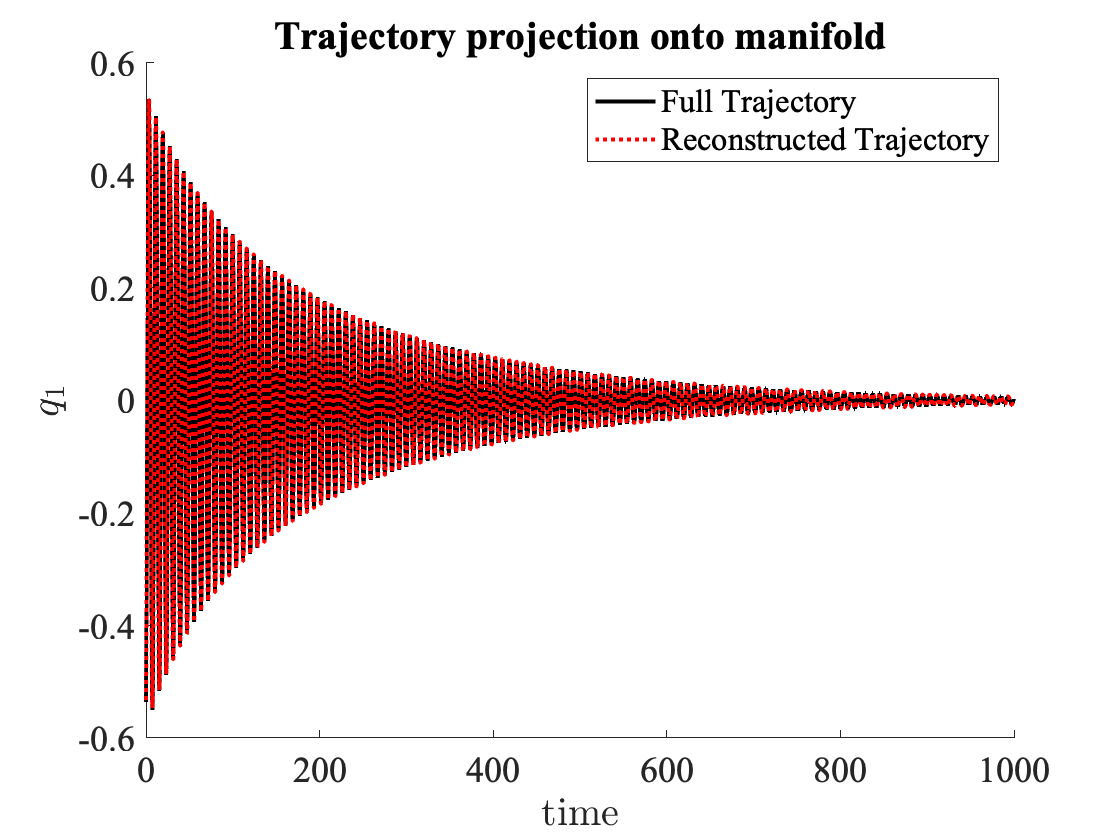

figure
hold on
plotCoord = 2;
plot(xSim{indTest(1),1}, xSim{indTest(1),2}(plotCoord,:),'k','Linewidth',2,'DisplayName','Full Trajectory')
xReconstructed = SSMFunction(V'*xSim{indTest(1),2});
plot(xSim{indTest(1),1}, xReconstructed(plotCoord,:),'r:','Linewidth',2,'DisplayName','Reconstructed Trajectory')

xlabel('time','Interpreter','latex')
ylabel('$q_1$','Interpreter','latex')
title('Trajectory projection onto manifold')
set(gca,'fontname','times')
set(gca,'fontsize',18)
legend

Furthermore, we draw the manifold shape along with the trajectories from the test set.

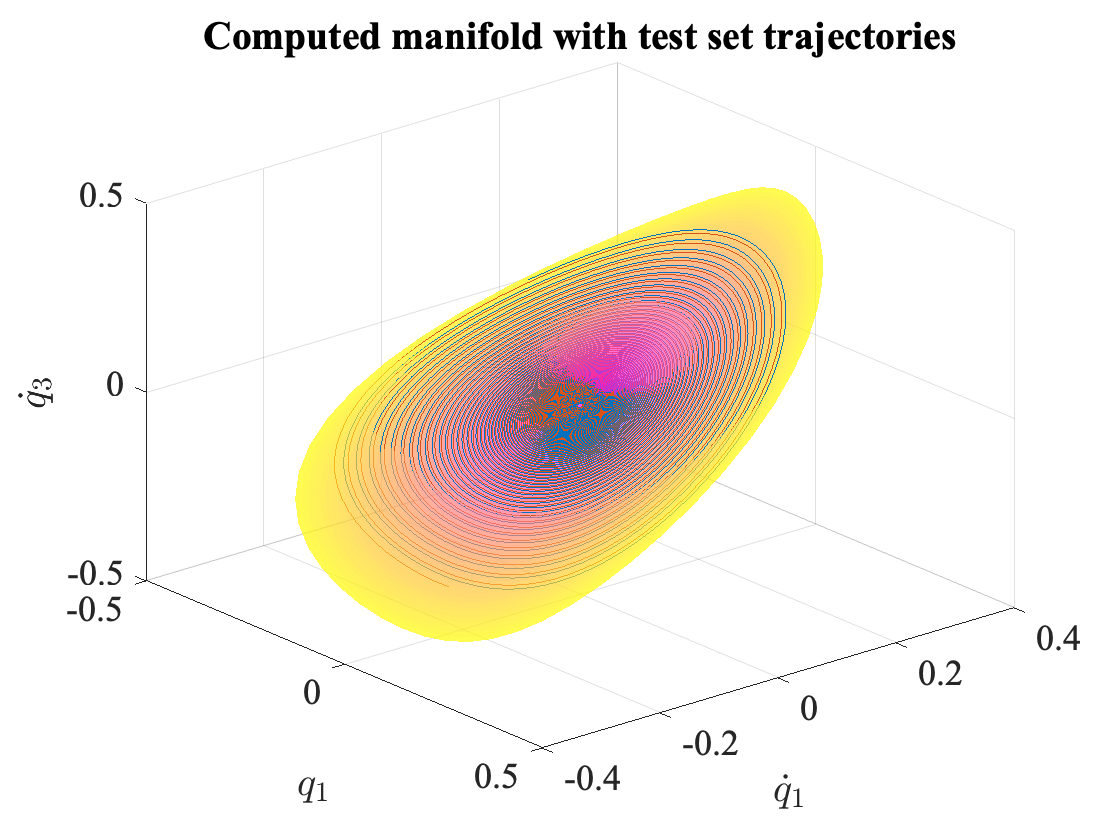

figure
hold on
plotRadius = 0.8;
plotInds = [1,4,6];
plotSSM(plotRadius, plotInds, SSMFunction);

for iTraj = indTest
    plot3(xSim{iTraj,2}(plotInds(1),:), xSim{iTraj,2}(plotInds(2),:), xSim{iTraj,2}(plotInds(3),:))
end

xlabel('$q_1$', 'Interpreter', 'latex')
ylabel('$\dot{q}_1$', 'Interpreter', 'latex')
zlabel('$\dot{q}_3$', 'Interpreter', 'latex')
title('Computed manifold with test set trajectories')
set(gca, 'fontname', 'times')
set(gca, 'fontsize', 18)
grid on
view(50, 30)